clear all
close all
clc
T = 178.5;
k = 0.212;
kp = 1;
kd = 10;
psi_d = 45;
v = 10;
del_t = 0.1;
t = 0:del_t:300;
d =k*kp*psi_d*pi/180/T;
c =k*kp/T;
b =(k+k*kd)/T;

odefun = @(t,z) [z(2); (d-b*z(2)-c*z(1))];
[t,z] = ode45(odefun,t,[0,0]);
psi = z(:,1);
yaw_rate = z(:,2);
i = 1;
x = [0];
while i < length(t)
    x(end+1) = x(end) + v*sin(psi(i))*del_t;
    i = i+1;
end

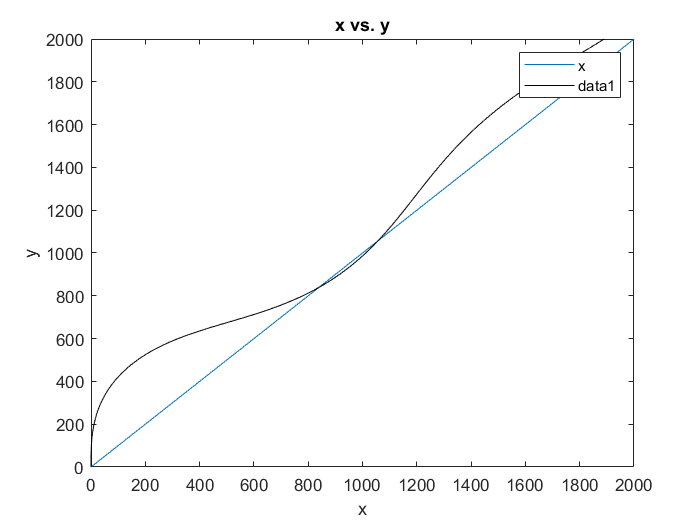

h2 = plot(10*x,10*x,"DisplayName","x");
legend
y = [0];
h = animatedline;
axis([0 2000 0 2000])
xlabel("x")
ylabel("y")
title("x vs. y")

for k = 1:length(x)
    if k == 1
        y(k) = 0 + v*cos(psi(k))*del_t;
    else
        y(k) = y(k-1) + v*cos(psi(k))*del_t;
    end
    addpoints(h,x(k),y(k));
    drawnow
end

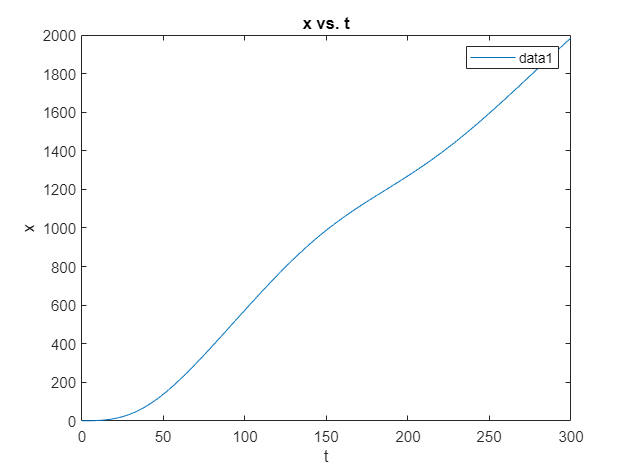

% Create plot of x and t
h3 = plot(t,x);

% Add xlabel, ylabel, title, and legend
xlabel("t")
ylabel("x")
title("x vs. t")
legend

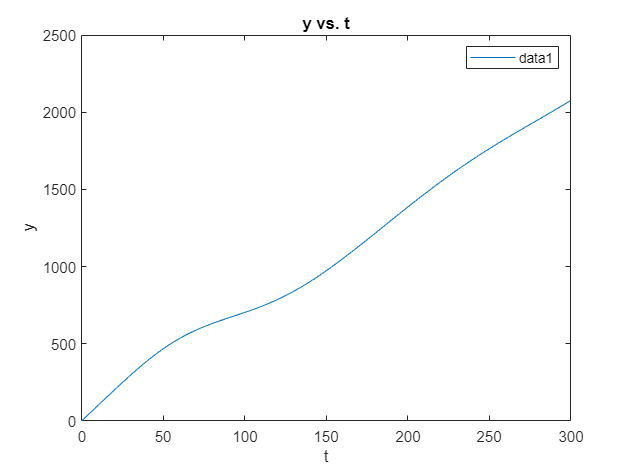

% Create plot of x and t
h3 = plot(t,y);

% Add xlabel, ylabel, title, and legend
xlabel("t")
ylabel("y")
title("y vs. t")
legend

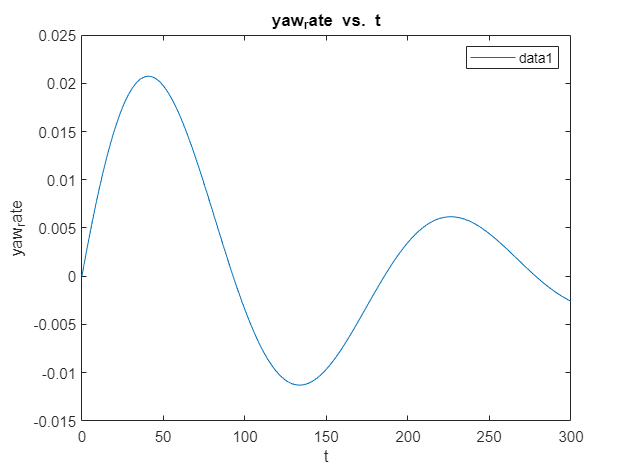

% Create plot of x and t
h3 = plot(t,yaw_rate);

% Add xlabel, ylabel, title, and legend
xlabel("t")
ylabel("yaw_rate")
title("yaw_rate vs. t")
legend

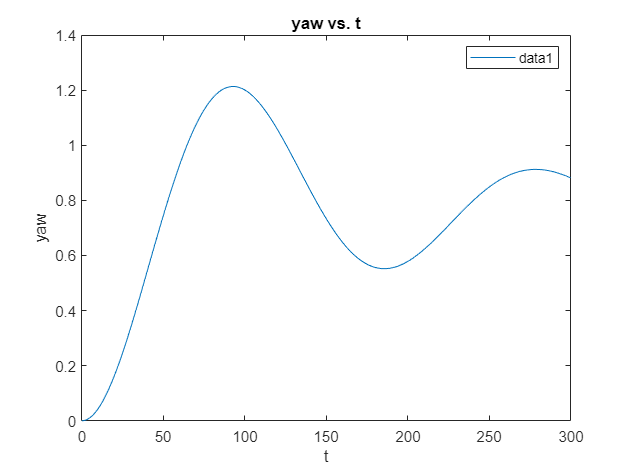

% Create plot of x and t
h3 = plot(t,psi);

% Add xlabel, ylabel, title, and legend
xlabel("t")
ylabel("yaw")
title("yaw vs. t")
legend